# A Pythagorean Trees

Careful use of HG transforms can save you a lot of headaches.

Here's what a pythagorean trio looks like.

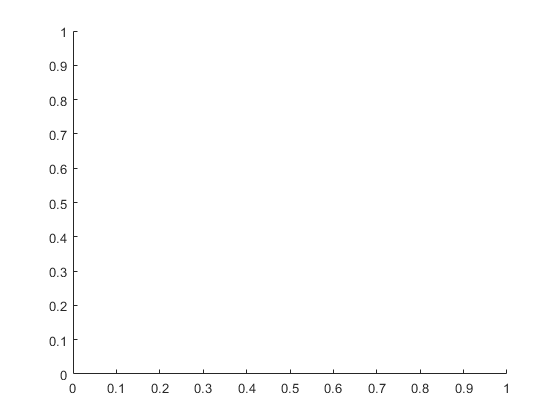

clf
gt = hgtransform('Parent',gca);


c = 1;
theta = 1.155;
maxdepth = 2;
pythag_seg(hgt,c,theta,maxdepth);

Undefined function or variable 'hgt'.


x = c*[0 0 1 1];
y = c*[0 1 1 0];
cmap = parula(maxdepth+1);
p = patch(x,y,cmap(1,:));

axis equal
axis off

## More depth to the tree

clf
hgt = hgtransform('Parent',gca);

c = 1;
theta = 1.155;
maxdepth = 5;
pythag_seg(hgt,c,theta,maxdepth);

x = c*[0 0 1 1];
y = c*[0 1 1 0];
cmap = parula(maxdepth+1);
p = patch(x,y,cmap(1,:));

axis equal
axis([-3.5 4.5 0 7])
axis off

## It's Alive!

This is what it looks like when we sweep theta from 0 to pi/2 and back.

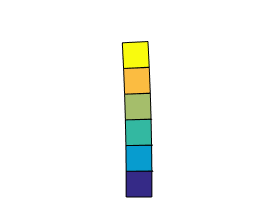

Here's the same thing, only looping back around directly from pi/2 to 0.

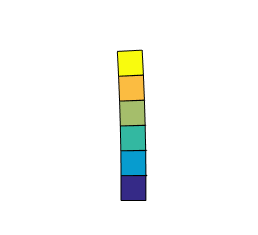

function pythag_seg(hgtp,c,theta,maxdepth,depth)
    
    if nargin < 5
        depth = 1;
    end
    
    depth = depth + 1;
    if depth > maxdepth
        return
    end
    
    hgtc1 = hgtransform('Parent',hgtp);
    hgtc2 = hgtransform('Parent',hgtp);
    
    x = c*[0 0 1 1];
    y = c*[0 1 1 0];
    
    cmap = parula(maxdepth+1);
    color = cmap(depth+1,:);
    patch(x,y,color,'EdgeColor','black','Parent',hgtc1);
    patch(x,y,color,'EdgeColor','black','Parent',hgtc2);
   
    a = c*cos(theta);
    b = c*sin(theta);
    
    Txy = makehgtform('translate',0,c,0);
    Rz  = makehgtform('zrotate',theta);
    S   = makehgtform('scale',a/c);
    set(hgtc1,'Matrix',Txy*Rz*S);
    
    Txy = makehgtform('translate',a*cos(theta),c+a*sin(theta),0);
    Rz  = makehgtform('zrotate',theta-pi/2);
    S   = makehgtform('scale',b/c);
    set(hgtc2,'Matrix',Txy*Rz*S);
    
    pythag_seg(hgtc1,c,theta,maxdepth,depth)
    pythag_seg(hgtc2,c,theta,maxdepth,depth)
    
end